%Loading the Data
load data\mnist_train.csv

%Showing n-th Image
n = 1;
img_matrix = reshape(mnist_train(n, 2:end), [28 28])'

img_matrix =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     3    18    18    18   126   136   175    26   166   255   247   1

digit = mnist_train(n, 1)

digit = 5

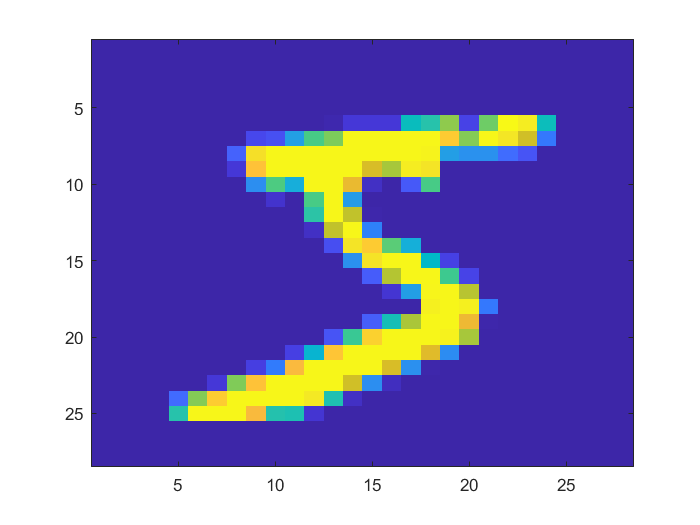

image(img_matrix)

%One Hot Encoding of Labels
labels = mnist_train(:, 1);
labels = categorical(labels);
labels = onehotencode(labels, 2);

%Building the Neural Network
layers = [784 16 16 10]

layers =    784    16    16    10



weights = {};
for i = 2:length(layers)
    weights = {weights{:}, -1 + 2.*rand(layers(i-1), layers(i))'};
end

%weights = {-1 + 2.*rand(neurons_input, neurons_hl(1))', -1 + 2.*rand(neurons_hl(1), neurons_hl(2))', -1 + 2.*rand(neurons_hl(2), neurons_output)'}
%weights{1}(1,1)

biases = {};
for i = 2:length(layers)
    biases = {biases{:}, -1 + 2.*rand(layers(i),1)};
end

%biases = {rand(neurons_hl(1), 1), rand(neurons_hl(2), 1), rand(neurons_output, 1)}
%biases{1}(1)


%Variables
lr = 0.05;
epochs = 50;

C = [];
for epoch = 1:epochs
epoch
for iter = 1:length(mnist_train)
%iter = n


%Setting Activations
activations = {1/256 * mnist_train(iter, 2:end)'};
for i = 2:length(layers)
    activations = {activations{:}, zeros(layers(i), 1)};
end

%activations = {1/256 * mnist_train(n, 2:end)', zeros(neurons_hl(1), 1), zeros(neurons_hl(2), 1), zeros(neurons_output, 1)}
%activations{2}(1)

epoch = 1

epoch = 2

epoch = 3

epoch = 4

epoch = 5

epoch = 6

epoch = 7

epoch = 8

epoch = 9

epoch = 10

epoch = 11

epoch = 12

epoch = 13

epoch = 14

epoch = 15

epoch = 16

epoch = 17

epoch = 18

epoch = 19

epoch = 20

epoch = 21

epoch = 22

epoch = 23

epoch = 24

epoch = 25

epoch = 26

epoch = 27

epoch = 28

epoch = 29

epoch = 30

epoch = 31

epoch = 32

epoch = 33

epoch = 34

epoch = 35

epoch = 36

epoch = 37

epoch = 38

epoch = 39

epoch = 40

epoch = 41

epoch = 42

epoch = 43

epoch = 44

epoch = 45

epoch = 46

epoch = 47

epoch = 48

epoch = 49

epoch = 50


%Pass Forward
for l = 2:length(layers)
    activations{l} = sigmoid(weights{l-1} * activations{l-1} + biases{l-1});
end

%Error Measure
C(end+1) = (activations{end}-labels(iter,:)')'*(activations{end}-labels(iter,:)');

%Backprop in last layer
l = 4;
dzw = activations{l-1};
daz = dsigmoid(weights{l-1} * activations{l-1} + biases{l-1});
dCa = 2 * (activations{end}-labels(iter,:)');

dCw_l = (dzw * (daz .* dCa)')';
dCb_l = daz .* dCa;

dCw = {};
dCb = {};
dCw = {dCw{:}, dCw_l};
dCb = {dCb{:}, dCb_l};

%Backpropogation in hidden layer
for l = 3:-1:2
dzw = activations{l-1};
daz = dsigmoid(weights{l-1} * activations{l-1} + biases{l-1});
%dCa = weights{l} * dsigmoid(weights{l}*activations{l-1}+biases{l}) * 2*(activations{l}-labels(iter,:))

%p1 =  weights{l}
%p2 =  dsigmoid(weights{l}*activations{l-1}+biases{l})
%p3 =  2*(activations{l}-labels(iter,:))

dCw_h = daz*dzw';
dCb_h = daz;

dCw = {dCw_h, dCw{:}};
dCb = {dCb_h, dCb{:}};
end
%dCw = (activations{l-1}) .* (dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})) .* (2 * (activations{end}-labels(n,:)'))
%dCb = (dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})) .* (2 * (activations{end}-labels(n,:)'))
%dCa = (weights{l-1}') * (dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})) * (2 * (activations{end}-labels(n,:)'))

%Updating the weights and biases
for l = 1:(length(layers)-1)
    weights{l} = weights{l} - lr*dCw{l};
    biases{l} = biases{l} - lr*dCb{l};
end

end

end

%Defining Functions

function y = sigmoid(z)
    y = (1./(1+exp(-z)));
end

function y = dsigmoid(z)
    y = sigmoid(z) .* (1-sigmoid(z));
end